# Calibration of the DR platform thermometer

Determine the 2D field-temperature calibration of the DR platform thermometer in order to analyze the MCE data. The calibration file only stores the calibration as a function of temperature, not as a function of field. However, the .raw file generated from the heat capacity measurements stores the values of temperature, magnetic field and thermometer resistance. Hence it is possible to extract from it the calibration of the thermometer for different values of magnetic field and interpolate / extrapolate it for the field range of interest.

Steps:

- Identify each line of raw file containing a field value

- for each "field=xxx" string, extract the field value

- For each value of field, store: field, thermometer resistance and temperature of the platform

- plot thermometer resistance versus field and temperature

- Find best result from interpolation / extrapolation / fit

- Invert the result in order to obtain temperature as a function of field and platform resistance

- Export the final result

## Import data

Data = importRawDataTable('2018-07-31_TmVO4-LS5228-DR-HC180731.raw')

## Store the row index of each magnetic field data info

FieldIndex = find(contains(Data.Comment,'Field'))%Find the index of the cells where the amplitude of
% the magnetic field was recorded
BeginIndex = find(contains(Data.Comment,'BEGIN'))%Find the index of the cells where a new set of data begins
Birn = 1:numel(BeginIndex)-1;%Row numbers of BeginIndex until the forelast row (Birn = Begin Index Row Numbers)
Bip = BeginIndex(Birn+1,:)-BeginIndex(Birn,:)%Subtraction of each row of BeginIndex from the next one
% Just to check that there is the same number of rows between each subset of data 
% separated by comments in the .raw file; (Bip = Begin Index Periodicity)
% The periodicity in the .raw file on 2018-07-31 is 307 rows

## Extract field value as numeric for each row of FieldIndex

StrFieldVal = erase(Data.Comment(FieldIndex),'Field=')% Each field comment is a string 
% formatted as 'Field=xxx' where xxx is the value of the field
% StrFieldVal is the array containing only the 'xxx' values, formatted as strings
FieldVal = str2double(StrFieldVal)

## Extract thermometer resistance and platform temperature for each field value

and store it in a structure called ThermHTCal with columns H (field), T (temperature) and R (platform thermometer resistance)

% For each value of field, make an array with FieldVal, ThermResOhms and PlatformTempKelvin
H = zeros(height(Data),1);%define the structure and its first column
H(1:BeginIndex(2)-1) = FieldVal(1);%The first block of data is different from the rest 
% because it has an extra line at the beginning
H(BeginIndex(2):BeginIndex(end)-1) = repelem(FieldVal(2:end-1),Bip(2:end));
% repelem(A,n) repeats each value of array A n times; 
% if n is an array, it will repeat A(1) n(1) times, A(2) n(2) times, etc.
H(BeginIndex(end):end) = FieldVal(end);% the last block of data is treated seperately
% because it is not included in Bip
check = isequal(H(FieldIndex),FieldVal);% check that the field value in each block of index i 
% of ThermHTCal.H is the same as FieldVal(i) by comparing the latter with 
% the value stored in line FieldIndex(i) of ThermHTCal.H; 
% if any line is different, isequal() will return 0
T = Data.PlatformTempKelvin;
R = Data.ThermResOhms;
ThermHTCal = cat(2,H,T,R);
ThermCal = repmat(ThermHTCal,1);
ThermCal(any(isnan(ThermCal), 2), :) = [];% Remove NAN rows
D = diff(ThermCal(:,2));% Calculate the differences between adjacent elements of T
ThmCal = ThermCal(D>0.0009,:);% Reduce the calibration array to only the elements for which T varies by more than 0.9mK

## Plot 2D curve R(H,T)

Hf = ThmCal(:,1);
Hf = round(Hf);
Tf = ThmCal(:,2);
Rf = ThmCal(:,3);
tstep = 0.05;
Hgl = 0:1000:10000;%
Tgl = logspace(-1,log10(3.8),40);%
[Hg,Tg] = meshgrid(Hgl,Tgl);%

Using griddata

Rg = griddata(Hf,Tf,Rf,Hg,Tg);
surfc(Hg,Tg,Rg)%
% ylim([0 4])

Using gridfit; this is too much like a black box

Rgl = gridfit(Hf,Tf,Rf,Hgl,Tgl);
surfc(Hg,Tg,Rgl)%

Using scatteredInterpolant; calculating Rvq takes several minutes and the result is not very convincing because the sampling in H is not fine enough

Rsi = scatteredInterpolant(Hf,Tf,Rf);% interpolate with a linear function
Rsi.Method = 'natural';
Rvq = Rsi(Hg,Tg);
surfc(Hg,Tg,Rvq)

Using sfit

[sf,gof] = fit([Hf,Tf],Rf,'poly23')
plot(sf,[Hf,Tf],Rf)
% gof = % goodness of fit
%            sse: 4.7008e+06
%        rsquare: 0.9840 <------ not great
%            dfe: 557
%     adjrsquare: 0.9838
%           rmse: 91.8667

myfittype = fittype('p00+p10*x+p01*y+p20*x^2+p02*y^2+p11*x*y+pi01/y', ...
    'dependent',{'z'},'independent',{'x','y'}, ...
    'coefficients',{'p00','p10','p01','p20','p02','p11','pi01'})
[sf,gof] = fit([Hf,Tf],Rf,myfittype)
plot(sf,[Hf,Tf],Rf)
% gof = 
%            sse: 3.1069e+05
%        rsquare: 0.9989 <------ better
%            dfe: 559
%     adjrsquare: 0.9989
%           rmse: 23.5755

Parameter p20=1.6e-6 does not seem very useful: for H=4000Oe, it changes Rf by only ~25 out of >10000 ==> will replace it with pi02

mft = fittype('p00+p10*x+p01*y+p02*y^2+p11*x*y+pi01/y+pi02/y^2', ...
    'dependent',{'z'},'independent',{'x','y'}, ...
    'coefficients',{'p00','p10','p01','p02','p11','pi01','pi02'})
[sf,gof] = fit([Hf,Tf],Rf,mft)
plot(sf,[Hf,Tf],Rf)
% gof = 
%            sse: 1.4914e+04
%        rsquare: 0.9999 <------ good!
%            dfe: 559
%     adjrsquare: 0.9999
%           rmse: 5.1652

p11 & p02 might also not be necessary >> remove

mft2 = fittype('p00+p10*x+p01*y+pi01/y+pi02/y^2', ...
    'dependent',{'z'},'independent',{'x','y'}, ...
    'coefficients',{'p00','p10','p01','pi01','pi02'})

mft2 =      General model:
     mft2(p00,p10,p01,pi01,pi02,x,y) = p00+p10*x+p01*y+pi01/y+pi02/y^2

[sf,gof] = fit([Hf,Tf],Rf,mft2)


     General model:
     sf(x,y) = p00+p10*x+p01*y+pi01/y+pi02/y^2
     Coefficients (with 95% confidence bounds):
       p00 =        2953  (2946, 2959)
       p10 =  -0.0006007  (-0.0009799, -0.0002215)
       p01 =      -90.66  (-92.22, -89.11)
       pi01 =        1402  (1397, 1408)
       pi02 =      -42.37  (-42.95, -41.78)



gof = struct with fields:
           sse: 3.2912e+04
       rsquare: 0.9999
           dfe: 561
    adjrsquare: 0.9999
          rmse: 7.6595


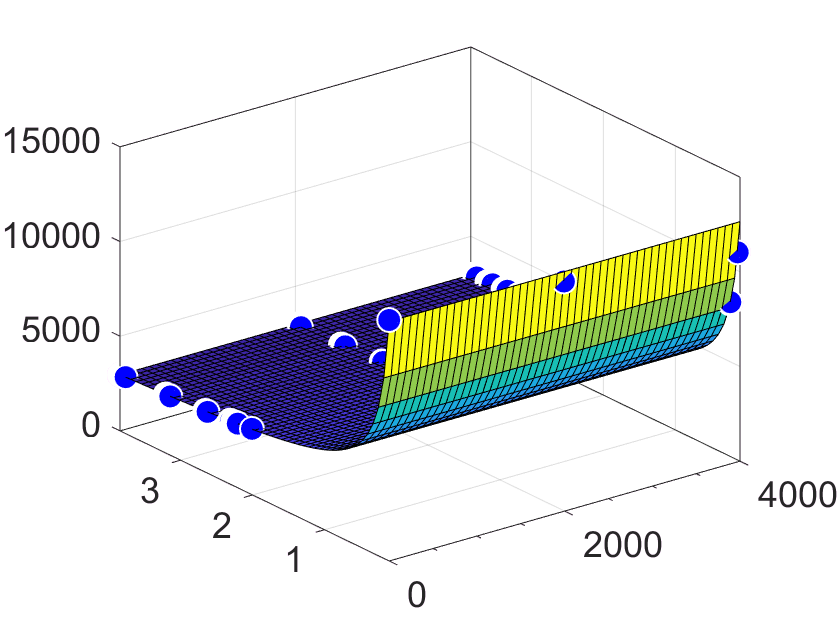

plot(sf,[Hf,Tf],Rf)

% gof = 
%            sse: 3.2912e+04
%        rsquare: 0.9999 <------ still good
%            dfe: 561
%     adjrsquare: 0.9999
%           rmse: 7.6595

figure
scatter3(Hf,Tf,Rf)
hold on
z = sf.p00 + sf.p10.*Hg + sf.p01.*Tg + sf.pi01./Tg + sf.pi02./Tg.^2;
surfc(Hgl,Tgl,z)
xlim([0,max(Hgl)])

## Temperature versus field and resistance

Now that we know how to get resistance from H & T, we want to be able to extract the value of temperature from H & R ==> same 

imft = fittype('p00+0*x+p01*y+pi01/(y-y1)', ...%p10*x gives p10~2e-7 /Oe, which is negligeable even at Hf=10^4 Oe
    'dependent',{'z'},'independent',{'x','y'}, ...
    'coefficients',{'p00','y1','p01','pi01'})

imft =      General model:
     imft(p00,y1,p01,pi01,x,y) = p00+0*x+p01*y+pi01/(y-y1)

[stf,gof] = fit([Hf,Rf],Tf,imft)


     General model:
     stf(x,y) = p00+0*x+p01*y+pi01/(y-y1)
     Coefficients (with 95% confidence bounds):
       p00 =     -0.6053  (-0.6281, -0.5824)
       y1 =        2282  (2278, 2285)
       p01 =   3.537e-05  (3.349e-05, 3.725e-05)
       pi01 =        2985  (2958, 3013)



gof = struct with fields:
           sse: 0.0110
       rsquare: 0.9999
           dfe: 562
    adjrsquare: 0.9999
          rmse: 0.0044


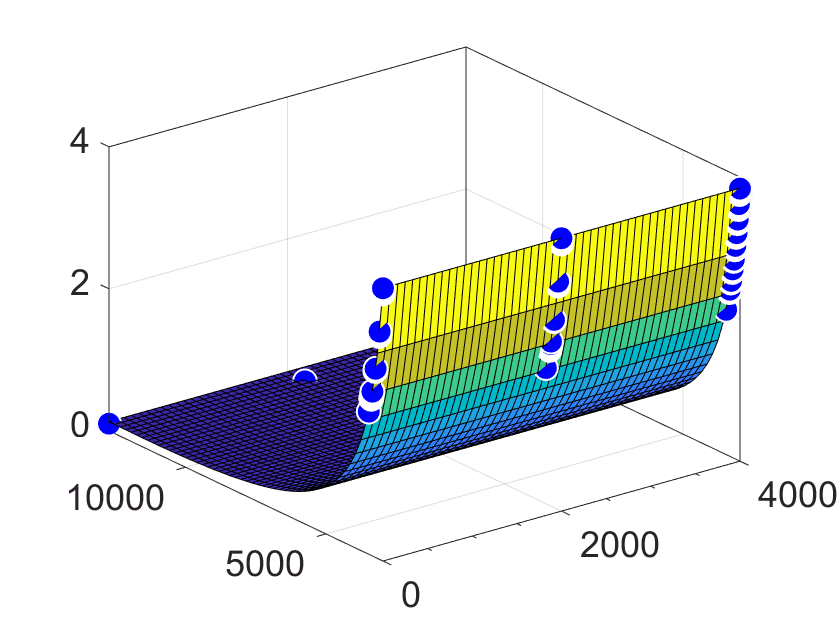

plot(stf,[Hf,Rf],Tf)

% gof = 
%            sse: 0.0110
%        rsquare: 0.9999
%            dfe: 562
%     adjrsquare: 0.9999
%           rmse: 0.0044

sfit variable 'stf' was saved as 'DR_thermometer_TvsHR_fit.mat' by simply right-clicking on it in the workspace and "Save as"